## **Question 1**

- Consider the the Lorenz-96 model (4) with the setting used in Project 1. The data assimilation problem is posed over the interval [0, T], starting with initial background states from N (x b 0 , B0). Observations are available at times ti = i ∆t, i = 0, . . . , N, tN = T. Use your synthetic observations, observation error covariance, and observation operator from Project 1.

**The code below is taken from my Project 1 implementation.**

**1.1)**

- Implement the Lorenz-96 model (1) and solve it using a Matlab ode solver (ode45 or one integrator selected from MATLODE).

- Start with an initial condition where the states are drawn from a random distribution (e.g., x0 ∼N (0, 16)), then integrate for 5 time units. Save the result. This is our x[-1]true.

- Propagate for ∆t time units, and save. This is our reference state x[0]true.

- (You can use ∆t = 0.1.)

clear;
close all;
clc;

% Setting seed for reproducibility
rng(381996)

% Importing Lorenz96 model
m = otp.lorenz63.presets.Canonical;

% Model configurations
n_states = 3;
n_obs = 1000 % Number of observations

n_obs = 1000

n_obs_states = 2;
x0 = normrnd(0,sqrt(16),[n_states,1]); % Inital condition of y0 drawn from N(0,16)
dt = 0.05; % time step unit

% Solving for for 5 time units (0.5) using inital conditions above
[~, x] = ode45(m.RHS.F, [0 dt*5], x0); % This is x[-1]true/reference state.
x_true_n1 = x(end,:).'; % Extracting states at final timestep

% Propogating for dt
[~, x] = ode45(m.RHS.F, [dt*5, dt*6], x_true_n1); % This is x[-1]true/reference state
x_true = x(end,:).'; % Extracting states at final timestep

**1.2)**

- Compute Nens normal random perturbations εbi ∼ N (0, σ2 INstate ) with σ = 0.2.

- Add to x[-1]true, and integrate the system starting from the perturbed initial conditions for ∆t time units.

- Save the resulting Nens states x. The members of this ensemble represent our set of background states Xb[0] .

n_ens = 1000;
sigma = 0.2;

% create ensemble members from perturbations of x_true
eps = normrnd(0,sigma,[n_states,n_ens]); % Perturbations (note normrnd(mu,sigma))
x_perturbed_n1 = x_true_n1 + eps;  % Adding to x_true[-1]

% init storage for ensemble (background state)
X_b_ens = zeros(n_states, n_ens);

% intergate system for one time unit for each ensemble member, store result
for i = 1:n_ens
    [~, x_ens] = ode45(m.RHS.F, [dt*5, dt*6], x_perturbed_n1(:, i));
    X_b_ens(:, i) = x_ens(end, :);
end

**1.3)**

- Using a large number of ensemble members compute the ensemble covariance Pb0.

- Check its condition number. If it is large build a modified background covariance that leads to a reasonably small condition number of the resulting covariance.

- This is our B0.

% A problem is called well-conditioned, if its condition number is small,
% i.e., in the order of 10, 100 or 1000
% and ill-conditioned if it is large: in the order of 10^6 - 10^10, and larger.
% https://cms.uni-konstanz.de/fileadmin/archive/informatik-saupe/fileadmin/informatik/ag-saupe/Webpages/lehre/na_08/Lab1/5_CondStab/html/CondStab.html

% Inbuilt covariance method
B0 = cov(X_b_ens.');
% Manual covariance check
X_ens_mean = mean(X_b_ens, 2);
X_delta = X_b_ens - X_ens_mean;
B0_manual = (1/(n_ens-1)).*(X_delta*X_delta.');

cond(B0), cond(B0_manual)

ans = 11.3549

ans = 11.3549

% Not needed as condition number is small
alpha = 0.001;
B0_downscale = (1-alpha)*B0 + alpha*eye(n_states);
cond(B0_downscale)

ans = 9.9081

% No need as already well conditioned
%B0 = B0_downscale

**1.4) **

- Obtain x0b by selecting one state with the smallest deviation from xtrue

[M,I] = min(sum(abs(X_b_ens - x_true(end,:).')));
x0b = X_b_ens(:, I)

x0b =   -19.9165
  -15.3658
   47.0913



% Hack work around as x0b was very far from the truth and all analysis
% probabilties were zero.
x0b = x_true

x0b =   -20.0487
  -16.0464
   47.1722


**1.5)**

- Run the reference trajectory starting from x_true[0] over the interval [0, T].

- Save the solution every ∆t time units.

- At each ti = i ∆t generate N_ens synthetic observations by adding to the reference solution H*xi normal random noise drawn from N (0, R), R = r^2 I N_obs, with r = 0.025.

T = 30;
time_steps = 0:dt:T;
x_start = x_true; % Storing inital x_true[0]

X_ref = zeros(n_states, length(time_steps));
X_ref(:, 1) = x_start;

% Run forward model and save results at each timestep
for t_id = 1:(length(time_steps)-1)
    [~, x] = ode45(m.RHS.F, [time_steps(t_id) time_steps(t_id)+dt], x_start);
    X_ref(:, t_id+1) = x(end,:);
    x_start = x(end,:).'; % For next iterations, use starting conditions based on prior state

end


% Apply observation operator and add random noise to reference trajectory

% Generating observation operator (observing every odd state)
A = eye(n_obs);
M = 1;
k = 1;
N = size(A);
H = reshape([reshape(A,M,[]);zeros(k,N(1)/M*N(2))],[],N(2)).';

% Redone such to only observe the first two states (For L63)
H = [1, 0, 0]

H =      1     0     0



% Applying observation vector to reference trajectory
% H * Reference -> Observations, Clone Observatations + noise -> ensemble 
X_obvs = H * X_ref;
X_obvs_ens = repmat(X_obvs, 1,1, n_obs);

% Generating and applying observation noise (for each ensemble member)
obvs_sigma = 0.025;
R = obvs_sigma.^2 * eye(n_obs_states);
obvs_noise = normrnd(0,obvs_sigma,size(X_obvs_ens));  % (note normrnd(mu,sigma))
X_obvs_ens = X_obvs_ens + obvs_noise;

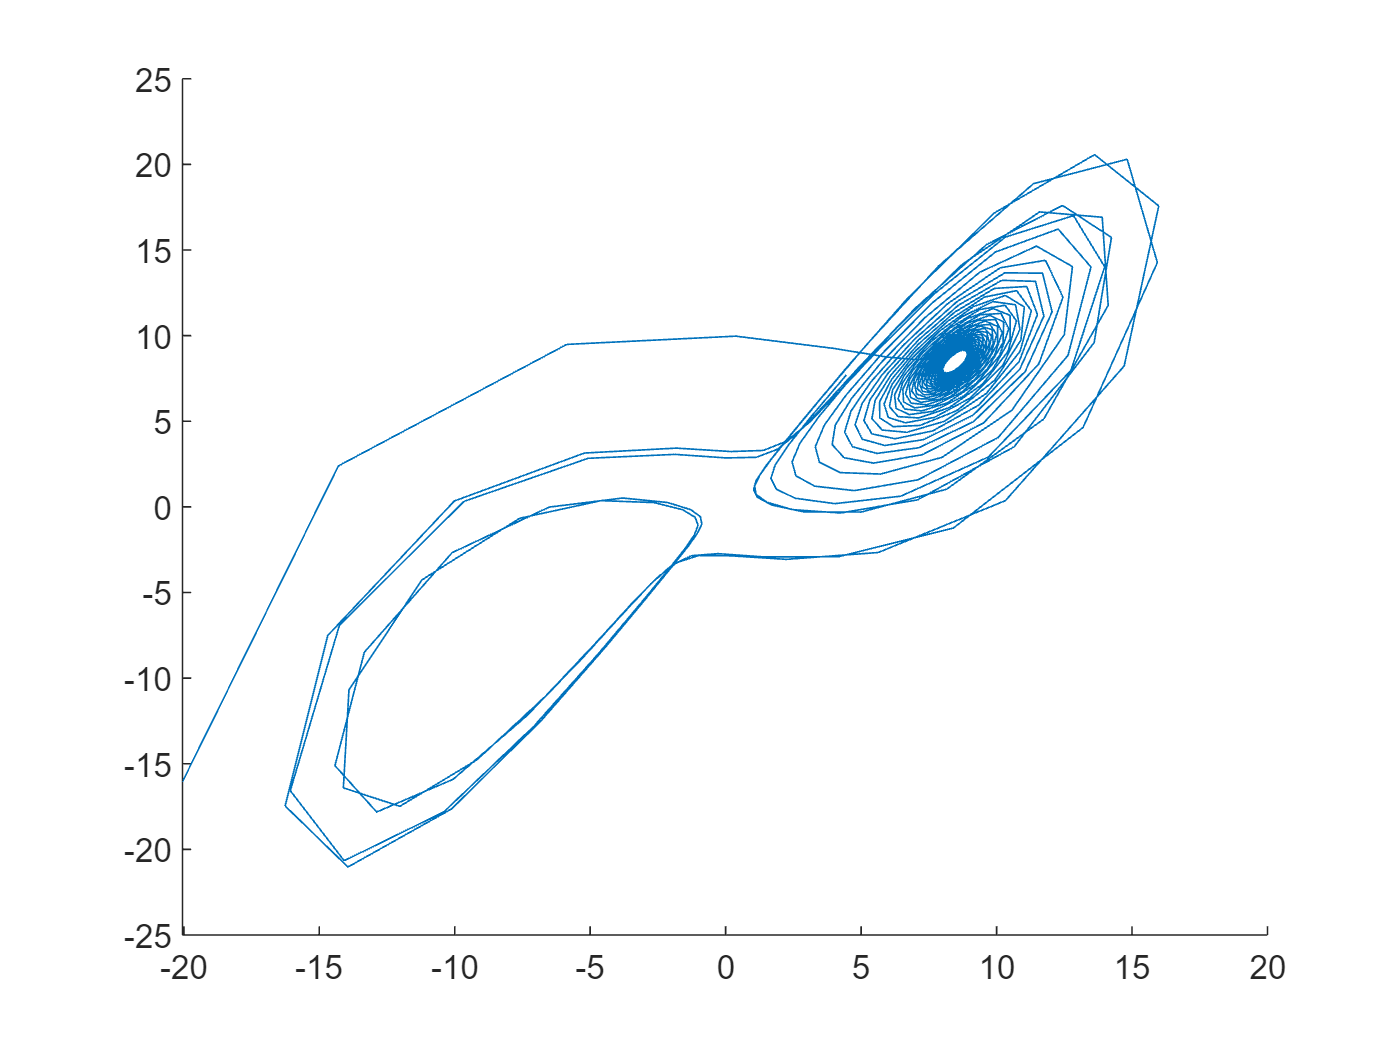

% Plotting sample reference and perturbed states (for 2 random ensemble members)
clf
hold on
plot(X_ref(1, :), X_ref(2, :));
%plot(X_obvs_ens(1, :, 1), X_obvs_ens(2, :, 1));

%plot(X_obvs_ens(1, :, 1), X_obvs_ens(2, :, 1));
%plot(X_obvs_ens(1, :, 2), X_obvs_ens(2, :, 2));
hold off

## **Question 2**

**2.1)**

- Consider the data assimilation problem posed over the interval [0, T], starting with initial background states from N (xb[0] , B0).

- Observations are available at times ti = i ∆t, i = 0, . . . , N, tN = T. Use your synthetic observations, observation error covariance, and observation operator from above.

% Unclear if these need to be resampled from this distribution or use the previously generated ensemble
n_particles = 1000

n_particles = 1000

X_ens_b = mvnrnd(x0b, B0, n_particles).'; 

**2.2)**

- Solve the data assimilation problem using the standard sequential importance with resampling (SIR) particle filter. 

- Resample when the effective number of particles decreases below a fraction of the total number, Neff ens ≤ α Nens, with 0 < α < 1 a tuning parameter under your control.

w = 1.0e-03 *

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


X_prediction =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans = 0

ans = 0.0070

ans = 0.0500

ans = 0.0076

Reampling!


ans = 0.1000

ans = 0.0117

ans = 0.1500

ans = 0.0103

ans = 0.2000

ans = 0.0094

Reampling!


ans = 0.2500

ans = 0.0074

ans = 0.3000

ans = 0.0071

ans = 0.3500

ans = 0.0078

ans = 0.4000

ans = 0.0079

ans = 0.4500

ans = 0.0067

ans = 0.5000

ans = 0.0079

Reampling!


ans = 0.5500

ans = 0.0064

ans = 0.6000

ans = 0.0043

ans = 0.6500

ans = 0.0037

ans = 0.7000

ans = 0.0032

ans = 0.7500

ans = 0.0027

ans = 0.8000

ans = 0.0024

ans = 0.8500

ans = 0.0018

Reampling!


ans = 0.9000

ans = 0.0022

ans = 0.9500

ans = 0.0015

ans = 1

ans = 0.0014

ans = 1.0500

ans = 0.0015

ans = 1.1000

ans = 0.0012

ans = 1.1500

ans = 4.3363e-04

ans = 1.2000

ans = 5.8173e-04

ans = 1.2500

ans = 6.8409e-04

Reampling!


ans = 1.3000

ans = 3.9230e-04

ans = 1.3500

ans = 3.1695e-04

ans = 1.4000

ans = 7.3029e-04

ans = 1.4500

ans = 0.0013

ans = 1.5000

ans = 0.0020

ans = 1.5500

ans = 0.0021

ans = 1.6000

ans = 0.0018

ans = 1.6500

ans = 0.0019

Reampling!


ans = 1.7000

ans = 0.0027

ans = 1.7500

ans = 0.0035

ans = 1.8000

ans = 0.0034

ans = 1.8500

ans = 0.0032

ans = 1.9000

ans = 0.0030

ans = 1.9500

ans = 0.0030

ans = 2

ans = 0.0036

ans = 2.0500

ans = 0.0040

ans = 2.1000

ans = 0.0036

Reampling!


ans = 2.1500

ans = 0.0032

ans = 2.2000

ans = 0.0030

ans = 2.2500

ans = 0.0031

ans = 2.3000

ans = 0.0032

ans = 2.3500

ans = 0.0042

ans = 2.4000

ans = 0.0040

ans = 2.4500

ans = 0.0034

ans = 2.5000

ans = 0.0033

ans = 2.5500

ans = 0.0033

Reampling!


ans = 2.6000

ans = 0.0045

ans = 2.6500

ans = 0.0053

ans = 2.7000

ans = 0.0048

ans = 2.7500

ans = 0.0044

ans = 2.8000

ans = 0.0041

ans = 2.8500

ans = 0.0042

ans = 2.9000

ans = 0.0043

ans = 2.9500

ans = 0.0057

ans = 3

ans = 0.0055

Reampling!


ans = 3.0500

ans = 0.0051

ans = 3.1000

ans = 0.0046

ans = 3.1500

ans = 0.0048

ans = 3.2000

ans = 0.0051

ans = 3.2500

ans = 0.0061

ans = 3.3000

ans = 0.0058

ans = 3.3500

ans = 0.0050

ans = 3.4000

ans = 0.0047

ans = 3.4500

ans = 0.0047

ans = 3.5000

ans = 0.0045

Reampling!


ans = 3.5500

ans = 0.0061

ans = 3.6000

ans = 0.0062

ans = 3.6500

ans = 0.0054

ans = 3.7000

ans = 0.0052

ans = 3.7500

ans = 0.0053

ans = 3.8000

ans = 0.0053

ans = 3.8500

ans = 0.0066

ans = 3.9000

ans = 0.0066

ans = 3.9500

ans = 0.0054

Reampling!


ans = 4

ans = 0.0053

ans = 4.0500

ans = 0.0051

ans = 4.1000

ans = 0.0048

ans = 4.1500

ans = 0.0064

ans = 4.2000

ans = 0.0070

ans = 4.2500

ans = 0.0057

ans = 4.3000

ans = 0.0059

ans = 4.3500

ans = 0.0057

ans = 4.4000

ans = 0.0050

ans = 4.4500

ans = 0.0069

Reampling!


ans = 4.5000

ans = 0.0070

ans = 4.5500

ans = 0.0056

ans = 4.6000

ans = 0.0056

ans = 4.6500

ans = 0.0053

ans = 4.7000

ans = 0.0053

ans = 4.7500

ans = 0.0062

ans = 4.8000

ans = 0.0074

ans = 4.8500

ans = 0.0067

ans = 4.9000

ans = 0.0065

Reampling!


ans = 4.9500

ans = 0.0061

ans = 5

ans = 0.0059

ans = 5.0500

ans = 0.0068

ans = 5.1000

ans = 0.0077

ans = 5.1500

ans = 0.0068

ans = 5.2000

ans = 0.0059

ans = 5.2500

ans = 0.0055

ans = 5.3000

ans = 0.0057

ans = 5.3500

ans = 0.0052

Reampling!


ans = 5.4000

ans = 0.0073

ans = 5.4500

ans = 0.0075

ans = 5.5000

ans = 0.0063

ans = 5.5500

ans = 0.0061

ans = 5.6000

ans = 0.0061

ans = 5.6500

ans = 0.0059

ans = 5.7000

ans = 0.0076

ans = 5.7500

ans = 0.0075

ans = 5.8000

ans = 0.0058

Reampling!


ans = 5.8500

ans = 0.0059

ans = 5.9000

ans = 0.0056

ans = 5.9500

ans = 0.0056

ans = 6

ans = 0.0065

ans = 6.0500

ans = 0.0078

ans = 6.1000

ans = 0.0069

ans = 6.1500

ans = 0.0066

ans = 6.2000

ans = 0.0062

ans = 6.2500

ans = 0.0058

ans = 6.3000

ans = 0.0069

Reampling!


ans = 6.3500

ans = 0.0078

ans = 6.4000

ans = 0.0070

ans = 6.4500

ans = 0.0059

ans = 6.5000

ans = 0.0056

ans = 6.5500

ans = 0.0057

ans = 6.6000

ans = 0.0051

ans = 6.6500

ans = 0.0073

ans = 6.7000

ans = 0.0076

ans = 6.7500

ans = 0.0064

Reampling!


ans = 6.8000

ans = 0.0062

ans = 6.8500

ans = 0.0060

ans = 6.9000

ans = 0.0056

ans = 6.9500

ans = 0.0074

ans = 7

ans = 0.0075

ans = 7.0500

ans = 0.0060

ans = 7.1000

ans = 0.0057

ans = 7.1500

ans = 0.0052

ans = 7.2000

ans = 0.0054

ans = 7.2500

ans = 0.0061

Reampling!


ans = 7.3000

ans = 0.0076

ans = 7.3500

ans = 0.0067

ans = 7.4000

ans = 0.0064

ans = 7.4500

ans = 0.0060

ans = 7.5000

ans = 0.0057

ans = 7.5500

ans = 0.0067

ans = 7.6000

ans = 0.0076

ans = 7.6500

ans = 0.0067

ans = 7.7000

ans = 0.0056

ans = 7.7500

ans = 0.0053

Reampling!


ans = 7.8000

ans = 0.0054

ans = 7.8500

ans = 0.0049

ans = 7.9000

ans = 0.0069

ans = 7.9500

ans = 0.0070

ans = 8

ans = 0.0060

ans = 8.0500

ans = 0.0057

ans = 8.1000

ans = 0.0057

ans = 8.1500

ans = 0.0056

ans = 8.2000

ans = 0.0069

ans = 8.2500

ans = 0.0068

Reampling!


ans = 8.3000

ans = 0.0054

ans = 8.3500

ans = 0.0054

ans = 8.4000

ans = 0.0051

ans = 8.4500

ans = 0.0050

ans = 8.5000

ans = 0.0061

ans = 8.5500

ans = 0.0071

ans = 8.6000

ans = 0.0057

ans = 8.6500

ans = 0.0059

ans = 8.7000

ans = 0.0056

ans = 8.7500

ans = 0.0049

Reampling!


ans = 8.8000

ans = 0.0068

ans = 8.8500

ans = 0.0071

ans = 8.9000

ans = 0.0061

ans = 8.9500

ans = 0.0055

ans = 9

ans = 0.0049

ans = 9.0500

ans = 0.0052

ans = 9.1000

ans = 0.0053

ans = 9.1500

ans = 0.0070

ans = 9.2000

ans = 0.0064

Reampling!


ans = 9.2500

ans = 0.0062

ans = 9.3000

ans = 0.0057

ans = 9.3500

ans = 0.0055

ans = 9.4000

ans = 0.0063

ans = 9.4500

ans = 0.0073

ans = 9.5000

ans = 0.0067

ans = 9.5500

ans = 0.0056

ans = 9.6000

ans = 0.0054

ans = 9.6500

ans = 0.0053

Reampling!


ans = 9.7000

ans = 0.0049

ans = 9.7500

ans = 0.0062

ans = 9.8000

ans = 0.0068

ans = 9.8500

ans = 0.0055

ans = 9.9000

ans = 0.0055

ans = 9.9500

ans = 0.0054

ans = 10

ans = 0.0050

ans = 10.0500

ans = 0.0066

ans = 10.1000

ans = 0.0066

Reampling!


ans = 10.1500

ans = 0.0058

ans = 10.2000

ans = 0.0052

ans = 10.2500

ans = 0.0047

ans = 10.3000

ans = 0.0050

ans = 10.3500

ans = 0.0052

ans = 10.4000

ans = 0.0067

ans = 10.4500

ans = 0.0060

ans = 10.5000

ans = 0.0056

ans = 10.5500

ans = 0.0052

ans = 10.6000

ans = 0.0050

Reampling!


ans = 10.6500

ans = 0.0058

ans = 10.7000

ans = 0.0066

ans = 10.7500

ans = 0.0060

ans = 10.8000

ans = 0.0048

ans = 10.8500

ans = 0.0045

ans = 10.9000

ans = 0.0044

ans = 10.9500

ans = 0.0041

ans = 11

ans = 0.0054

ans = 11.0500

ans = 0.0058

ans = 11.1000

ans = 0.0050

Reampling!


ans = 11.1500

ans = 0.0049

ans = 11.2000

ans = 0.0048

ans = 11.2500

ans = 0.0048

ans = 11.3000

ans = 0.0060

ans = 11.3500

ans = 0.0058

ans = 11.4000

ans = 0.0049

ans = 11.4500

ans = 0.0043

ans = 11.5000

ans = 0.0038

ans = 11.5500

ans = 0.0040

Reampling!


ans = 11.6000

ans = 0.0039

ans = 11.6500

ans = 0.0050

ans = 11.7000

ans = 0.0045

ans = 11.7500

ans = 0.0042

ans = 11.8000

ans = 0.0038

ans = 11.8500

ans = 0.0034

ans = 11.9000

ans = 0.0043

ans = 11.9500

ans = 0.0046

ans = 12

ans = 0.0041

ans = 12.0500

ans = 0.0034

Reampling!


ans = 12.1000

ans = 0.0034

ans = 12.1500

ans = 0.0035

ans = 12.2000

ans = 0.0032

ans = 12.2500

ans = 0.0046

ans = 12.3000

ans = 0.0048

ans = 12.3500

ans = 0.0041

ans = 12.4000

ans = 0.0038

ans = 12.4500

ans = 0.0037

ans = 12.5000

ans = 0.0036

Reampling!


ans = 12.5500

ans = 0.0053

ans = 12.6000

ans = 0.0054

ans = 12.6500

ans = 0.0045

ans = 12.7000

ans = 0.0039

ans = 12.7500

ans = 0.0035

ans = 12.8000

ans = 0.0036

ans = 12.8500

ans = 0.0035

ans = 12.9000

ans = 0.0047

ans = 12.9500

ans = 0.0041

ans = 13

ans = 0.0040

Reampling!


ans = 13.0500

ans = 0.0039

ans = 13.1000

ans = 0.0037

ans = 13.1500

ans = 0.0043

ans = 13.2000

ans = 0.0048

ans = 13.2500

ans = 0.0045

ans = 13.3000

ans = 0.0037

ans = 13.3500

ans = 0.0034

ans = 13.4000

ans = 0.0031

ans = 13.4500

ans = 0.0031

ans = 13.5000

ans = 0.0035

Reampling!


ans = 13.5500

ans = 0.0038

ans = 13.6000

ans = 0.0031

ans = 13.6500

ans = 0.0030

ans = 13.7000

ans = 0.0029

ans = 13.7500

ans = 0.0027

ans = 13.8000

ans = 0.0034

ans = 13.8500

ans = 0.0035

ans = 13.9000

ans = 0.0034

ans = 13.9500

ans = 0.0029

ans = 14

ans = 0.0028

Reampling!


ans = 14.0500

ans = 0.0026

ans = 14.1000

ans = 0.0025

ans = 14.1500

ans = 0.0032

ans = 14.2000

ans = 0.0034

ans = 14.2500

ans = 0.0029

ans = 14.3000

ans = 0.0026

ans = 14.3500

ans = 0.0025

ans = 14.4000

ans = 0.0028

ans = 14.4500

ans = 0.0031

ans = 14.5000

ans = 0.0033

Reampling!


ans = 14.5500

ans = 0.0030

ans = 14.6000

ans = 0.0024

ans = 14.6500

ans = 0.0023

ans = 14.7000

ans = 0.0024

ans = 14.7500

ans = 0.0022

ans = 14.8000

ans = 0.0030

ans = 14.8500

ans = 0.0028

ans = 14.9000

ans = 0.0027

ans = 14.9500

ans = 0.0024

ans = 15

ans = 0.0025

Reampling!


ans = 15.0500

ans = 0.0025

ans = 15.1000

ans = 0.0031

ans = 15.1500

ans = 0.0033

ans = 15.2000

ans = 0.0033

ans = 15.2500

ans = 0.0025

ans = 15.3000

ans = 0.0025

ans = 15.3500

ans = 0.0025

ans = 15.4000

ans = 0.0024

ans = 15.4500

ans = 0.0030

ans = 15.5000

ans = 0.0030

Reampling!


ans = 15.5500

ans = 0.0027

ans = 15.6000

ans = 0.0024

ans = 15.6500

ans = 0.0025

ans = 15.7000

ans = 0.0024

ans = 15.7500

ans = 0.0032

ans = 15.8000

ans = 0.0036

ans = 15.8500

ans = 0.0036

ans = 15.9000

ans = 0.0031

ans = 15.9500

ans = 0.0031

Reampling!


ans = 16

ans = 0.0028

ans = 16.0500

ans = 0.0027

ans = 16.1000

ans = 0.0032

ans = 16.1500

ans = 0.0029

ans = 16.2000

ans = 0.0025

ans = 16.2500

ans = 0.0022

ans = 16.3000

ans = 0.0022

ans = 16.3500

ans = 0.0021

ans = 16.4000

ans = 0.0028

ans = 16.4500

ans = 0.0033

Reampling!


ans = 16.5000

ans = 0.0033

ans = 16.5500

ans = 0.0027

ans = 16.6000

ans = 0.0025

ans = 16.6500

ans = 0.0025

ans = 16.7000

ans = 0.0021

ans = 16.7500

ans = 0.0028

ans = 16.8000

ans = 0.0022

ans = 16.8500

ans = 0.0020

ans = 16.9000

ans = 0.0015

ans = 16.9500

ans = 0.0015

Reampling!


ans = 17

ans = 0.0017

ans = 17.0500

ans = 0.0023

ans = 17.1000

ans = 0.0025

ans = 17.1500

ans = 0.0024

ans = 17.2000

ans = 0.0018

ans = 17.2500

ans = 0.0019

ans = 17.3000

ans = 0.0019

ans = 17.3500

ans = 0.0019

ans = 17.4000

ans = 0.0018

ans = 17.4500

ans = 0.0012

Reampling!


ans = 17.5000

ans = 6.5294e-04

ans = 17.5500

ans = 7.3629e-04

ans = 17.6000

ans = 5.9588e-04

ans = 17.6500

ans = 7.9792e-04

ans = 17.7000

ans = 6.2206e-04

ans = 17.7500

ans = 4.6046e-04

ans = 17.8000

ans = 1.9922e-04

ans = 17.8500

ans = 3.0146e-04

ans = 17.9000

ans = 2.5872e-04

ans = 17.9500

ans = 3.9948e-04

Reampling!


ans = 18

ans = 5.6493e-04

ans = 18.0500

ans = 9.2201e-04

ans = 18.1000

ans = 0.0012

ans = 18.1500

ans = 9.7961e-04

ans = 18.2000

ans = 7.0143e-04

ans = 18.2500

ans = 7.2267e-04

ans = 18.3000

ans = 8.1716e-04

ans = 18.3500

ans = 8.2578e-04

ans = 18.4000

ans = 0.0011

ans = 18.4500

ans = 0.0012

Reampling!


ans = 18.5000

ans = 0.0011

ans = 18.5500

ans = 0.0011

ans = 18.6000

ans = 9.1877e-04

ans = 18.6500

ans = 7.8208e-04

ans = 18.7000

ans = 0.0011

ans = 18.7500

ans = 8.2088e-04

ans = 18.8000

ans = 8.8978e-04

ans = 18.8500

ans = 7.9672e-04

ans = 18.9000

ans = 8.6019e-04

ans = 18.9500

ans = 8.8068e-04

Reampling!


ans = 19

ans = 7.9435e-04

ans = 19.0500

ans = 0.0015

ans = 19.1000

ans = 0.0018

ans = 19.1500

ans = 0.0021

ans = 19.2000

ans = 0.0022

ans = 19.2500

ans = 0.0021

ans = 19.3000

ans = 0.0023

ans = 19.3500

ans = 0.0026

ans = 19.4000

ans = 0.0020

Reampling!


ans = 19.4500

ans = 0.0022

ans = 19.5000

ans = 0.0019

ans = 19.5500

ans = 0.0019

ans = 19.6000

ans = 0.0020

ans = 19.6500

ans = 0.0024

ans = 19.7000

ans = 0.0033

ans = 19.7500

ans = 0.0036

ans = 19.8000

ans = 0.0033

ans = 19.8500

ans = 0.0038

Reampling!


ans = 19.9000

ans = 0.0035

ans = 19.9500

ans = 0.0035

ans = 20

ans = 0.0034

ans = 20.0500

ans = 0.0027

ans = 20.1000

ans = 0.0023

ans = 20.1500

ans = 0.0018

ans = 20.2000

ans = 0.0019

ans = 20.2500

ans = 0.0020

ans = 20.3000

ans = 0.0019

Reampling!


ans = 20.3500

ans = 0.0028

ans = 20.4000

ans = 0.0034

ans = 20.4500

ans = 0.0032

ans = 20.5000

ans = 0.0029

ans = 20.5500

ans = 0.0030

ans = 20.6000

ans = 0.0023

ans = 20.6500

ans = 0.0028

ans = 20.7000

ans = 0.0023

ans = 20.7500

ans = 0.0017

Reampling!


ans = 20.8000

ans = 0.0015

ans = 20.8500

ans = 0.0014

ans = 20.9000

ans = 0.0013

ans = 20.9500

ans = 0.0014

ans = 21

ans = 0.0012

ans = 21.0500

ans = 0.0010

ans = 21.1000

ans = 0.0013

ans = 21.1500

ans = 0.0017

ans = 21.2000

ans = 0.0017

ans = 21.2500

ans = 0.0015

Reampling!


ans = 21.3000

ans = 0.0018

ans = 21.3500

ans = 0.0019

ans = 21.4000

ans = 0.0017

ans = 21.4500

ans = 0.0016

ans = 21.5000

ans = 0.0014

ans = 21.5500

ans = 0.0016

ans = 21.6000

ans = 0.0016

ans = 21.6500

ans = 0.0020

ans = 21.7000

ans = 0.0021

Reampling!


ans = 21.7500

ans = 0.0019

ans = 21.8000

ans = 0.0023

ans = 21.8500

ans = 0.0019

ans = 21.9000

ans = 0.0023

ans = 21.9500

ans = 0.0018

ans = 22

ans = 0.0019

ans = 22.0500

ans = 0.0016

ans = 22.1000

ans = 0.0017

ans = 22.1500

ans = 0.0018

ans = 22.2000

ans = 0.0024

Reampling!


ans = 22.2500

ans = 0.0032

ans = 22.3000

ans = 0.0042

ans = 22.3500

ans = 0.0053

ans = 22.4000

ans = 0.0067

ans = 22.4500

ans = 0.0056

ans = 22.5000

ans = 0.0050

ans = 22.5500

ans = 0.0044

ans = 22.6000

ans = 0.0045

Reampling!


ans = 22.6500

ans = 0.0051

ans = 22.7000

ans = 0.0032

ans = 22.7500

ans = 0.0024

ans = 22.8000

ans = 0.0023

ans = 22.8500

ans = 0.0024

ans = 22.9000

ans = 0.0024

ans = 22.9500

ans = 0.0031

ans = 23

ans = 0.0047

ans = 23.0500

ans = 0.0057

Reampling!


ans = 23.1000

ans = 0.0076

ans = 23.1500

ans = 0.0069

ans = 23.2000

ans = 0.0048

ans = 23.2500

ans = 0.0049

ans = 23.3000

ans = 0.0040

ans = 23.3500

ans = 0.0041

ans = 23.4000

ans = 0.0022

Reampling!


ans = 23.4500

ans = 8.0187e-04

ans = 23.5000

ans = 4.5198e-04

ans = 23.5500

ans = 5.4262e-04

ans = 23.6000

ans = 6.1593e-04

ans = 23.6500

ans = 7.1797e-04

ans = 23.7000

ans = 7.5524e-04

ans = 23.7500

ans = 0.0012

ans = 23.8000

ans = 0.0013

ans = 23.8500

ans = 7.8289e-04

Reampling!


ans = 23.9000

ans = 0.0026

ans = 23.9500

ans = 0.0068

ans = 24

ans = 0.0105

ans = 24.0500

ans = 0.0081

Reampling!


ans = 24.1000

ans = 0.0087

ans = 24.1500

ans = 0.0065

ans = 24.2000

ans = 0.0055

ans = 24.2500

ans = 0.0031

ans = 24.3000

ans = 0.0018

ans = 24.3500

ans = 0.0011

ans = 24.4000

ans = 8.6807e-04

ans = 24.4500

ans = 7.6639e-04

Reampling!


ans = 24.5000

ans = 7.4470e-04

ans = 24.5500

ans = 7.8947e-04

ans = 24.6000

ans = 0.0012

ans = 24.6500

ans = 0.0018

ans = 24.7000

ans = 0.0023

ans = 24.7500

ans = 0.0021

ans = 24.8000

ans = 0.0026

ans = 24.8500

ans = 0.0023

ans = 24.9000

ans = 0.0026

Reampling!


ans = 24.9500

ans = 0.0018

ans = 25

ans = 0.0012

ans = 25.0500

ans = 9.0752e-04

ans = 25.1000

ans = 8.1197e-04

ans = 25.1500

ans = 8.3737e-04

ans = 25.2000

ans = 8.7532e-04

ans = 25.2500

ans = 8.4138e-04

ans = 25.3000

ans = 9.7170e-04

ans = 25.3500

ans = 0.0015

ans = 25.4000

ans = 0.0019

Reampling!


ans = 25.4500

ans = 0.0015

ans = 25.5000

ans = 0.0011

ans = 25.5500

ans = 0.0012

ans = 25.6000

ans = 0.0022

ans = 25.6500

ans = 0.0013

Reampling!


ans = 25.7000

ans = 8.2140e-04

ans = 25.7500

ans = 2.6006e-04

ans = 25.8000

ans = 9.3159e-04

ans = 25.8500

ans = 7.9068e-04

ans = 25.9000

ans = 5.2980e-04

ans = 25.9500

ans = 5.3250e-04

ans = 26

ans = 6.6962e-04

Reampling!


ans = 26.0500

ans = 0.0011

ans = 26.1000

ans = 0.0014

ans = 26.1500

ans = 0.0015

ans = 26.2000

ans = 0.0019

ans = 26.2500

ans = 0.0023

ans = 26.3000

ans = 0.0021

ans = 26.3500

ans = 0.0025

ans = 26.4000

ans = 0.0020

ans = 26.4500

ans = 0.0021

ans = 26.5000

ans = 0.0014

Reampling!


ans = 26.5500

ans = 0.0012

ans = 26.6000

ans = 8.1361e-04

ans = 26.6500

ans = 6.4157e-04

ans = 26.7000

ans = 5.5078e-04

ans = 26.7500

ans = 3.0857e-04

ans = 26.8000

ans = 6.2617e-04

ans = 26.8500

ans = 4.2490e-04

ans = 26.9000

ans = 0.0015

ans = 26.9500

ans = 0.0010

Reampling!


ans = 27

ans = 6.7729e-04

ans = 27.0500

ans = 0.0020

ans = 27.1000

ans = 9.4763e-04

ans = 27.1500

ans = 7.3235e-04

ans = 27.2000

ans = 7.2498e-04

Reampling!


ans = 27.2500

ans = 6.5150e-04

ans = 27.3000

ans = 4.5266e-04

ans = 27.3500

ans = 4.0923e-04

ans = 27.4000

ans = 4.1895e-04

ans = 27.4500

ans = 4.9358e-04

ans = 27.5000

ans = 5.8431e-04

ans = 27.5500

ans = 7.4298e-04

ans = 27.6000

ans = 0.0010

Reampling!


ans = 27.6500

ans = 0.0016

ans = 27.7000

ans = 0.0023

ans = 27.7500

ans = 0.0032

ans = 27.8000

ans = 0.0037

ans = 27.8500

ans = 0.0035

ans = 27.9000

ans = 0.0040

ans = 27.9500

ans = 0.0040

ans = 28

ans = 0.0039

ans = 28.0500

ans = 0.0026

Reampling!


ans = 28.1000

ans = 0.0021

ans = 28.1500

ans = 0.0018

ans = 28.2000

ans = 0.0019

ans = 28.2500

ans = 0.0023

ans = 28.3000

ans = 0.0026

ans = 28.3500

ans = 0.0032

ans = 28.4000

ans = 0.0039

ans = 28.4500

ans = 0.0052

Reampling!


ans = 28.5000

ans = 0.0086

ans = 28.5500

ans = 0.0107

ans = 28.6000

ans = 0.0121

ans = 28.6500

ans = 0.0117

Reampling!


ans = 28.7000

ans = 0.0091

ans = 28.7500

ans = 0.0078

ans = 28.8000

ans = 0.0070

ans = 28.8500

ans = 0.0051

ans = 28.9000

ans = 0.0024

ans = 28.9500

ans = 0.0013

Reampling!


ans = 29

ans = 6.6874e-04

ans = 29.0500

ans = 5.2595e-04

ans = 29.1000

ans = 4.5190e-04

ans = 29.1500

ans = 5.3259e-04

ans = 29.2000

ans = 6.2112e-04

ans = 29.2500

ans = 7.7326e-04

ans = 29.3000

ans = 9.0289e-04

ans = 29.3500

ans = 0.0012

ans = 29.4000

ans = 0.0010

ans = 29.4500

ans = 0.0012

ans = 29.5000

ans = 0.0010

Reampling!


ans = 29.5500

ans = 9.8251e-04

ans = 29.6000

ans = 7.3171e-04

ans = 29.6500

ans = 5.5607e-04

ans = 29.7000

ans = 4.0364e-04

ans = 29.7500

ans = 3.2787e-04

ans = 29.8000

ans = 4.4445e-04

ans = 29.8500

ans = 3.5489e-04

ans = 29.9000

ans = 2.3534e-04

ans = 29.9500

ans = 1.9312e-04

Reampling!


ans = 30

ans = 3.4336e-04

EnKF run complete


rmse_particle =     0.0077    0.0097    0.0125    0.0107    0.0100    0.0091    0.0094    0.0098    0.0085    0.0084    0.0080    0.0066    0.0054    0.0044    0.0037    0.0031    0.0026    0.0018    0.0024    0.0019    0.0017    0.0016    0.0013    0.0005    0.0007    0.0008    0.0005    0.0003    0.0007    0.0014    0.0024    0.0026    0.0021    0.0021    0.0030    0.0036    0.0040    0.0038    0.0036    0.0035    0.0038    0.0041    0.0041    0.0040    0.0036    0.0034    0.0036    0.0042    0.0045    0.0041


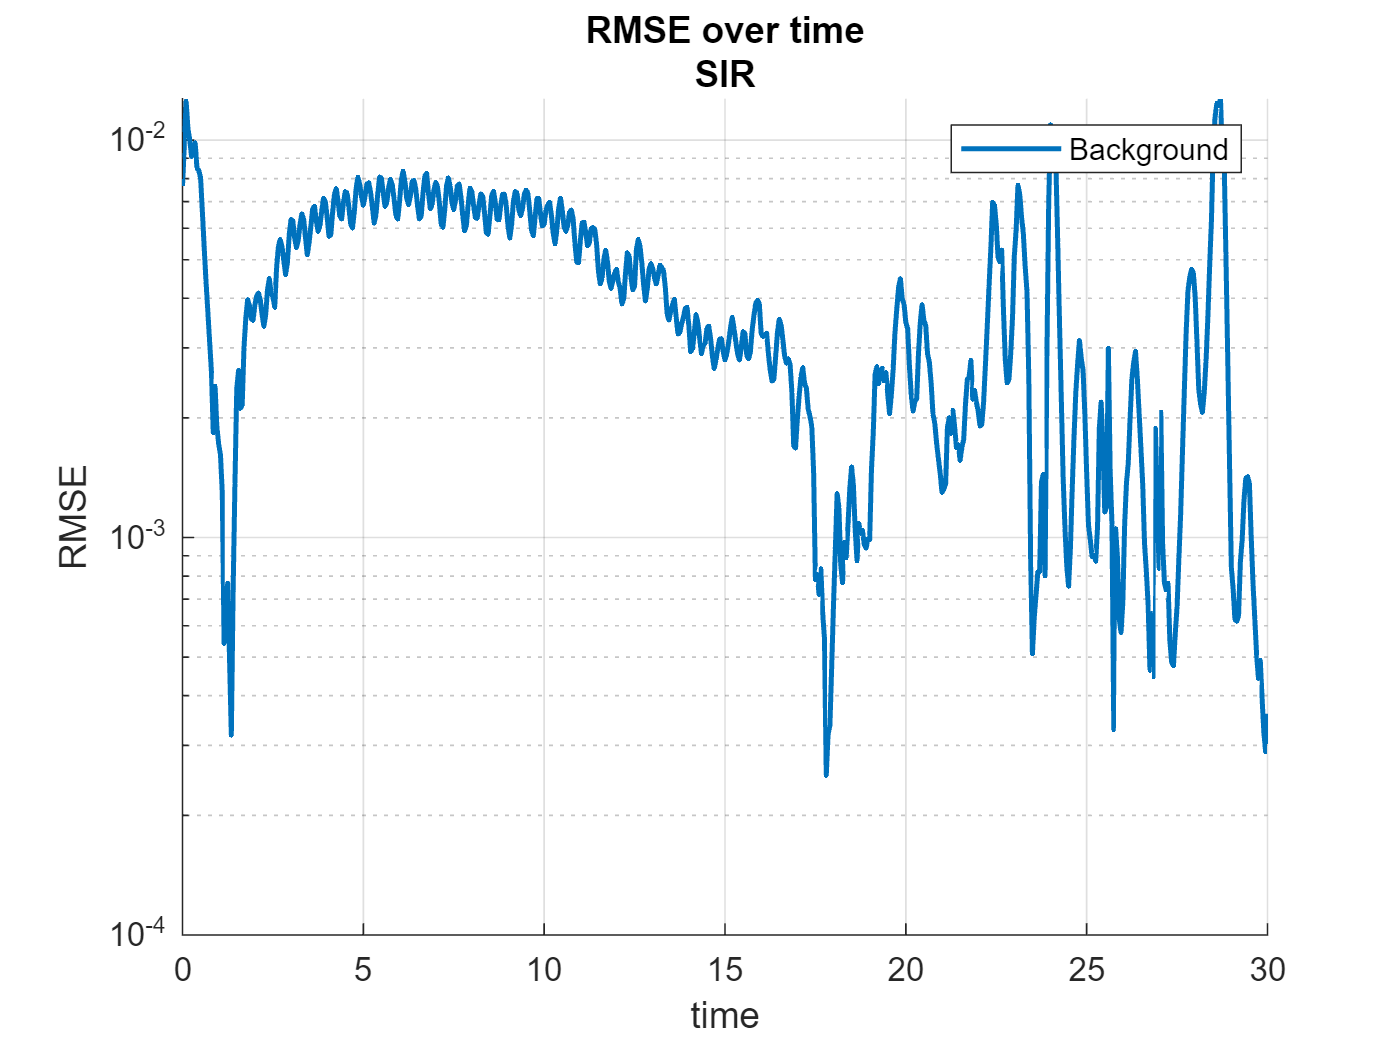

prediction = donald_SIR_63b(m, X_ens_b, X_obvs_ens, X_ref, H, time_steps, n_states, n_particles, 1);

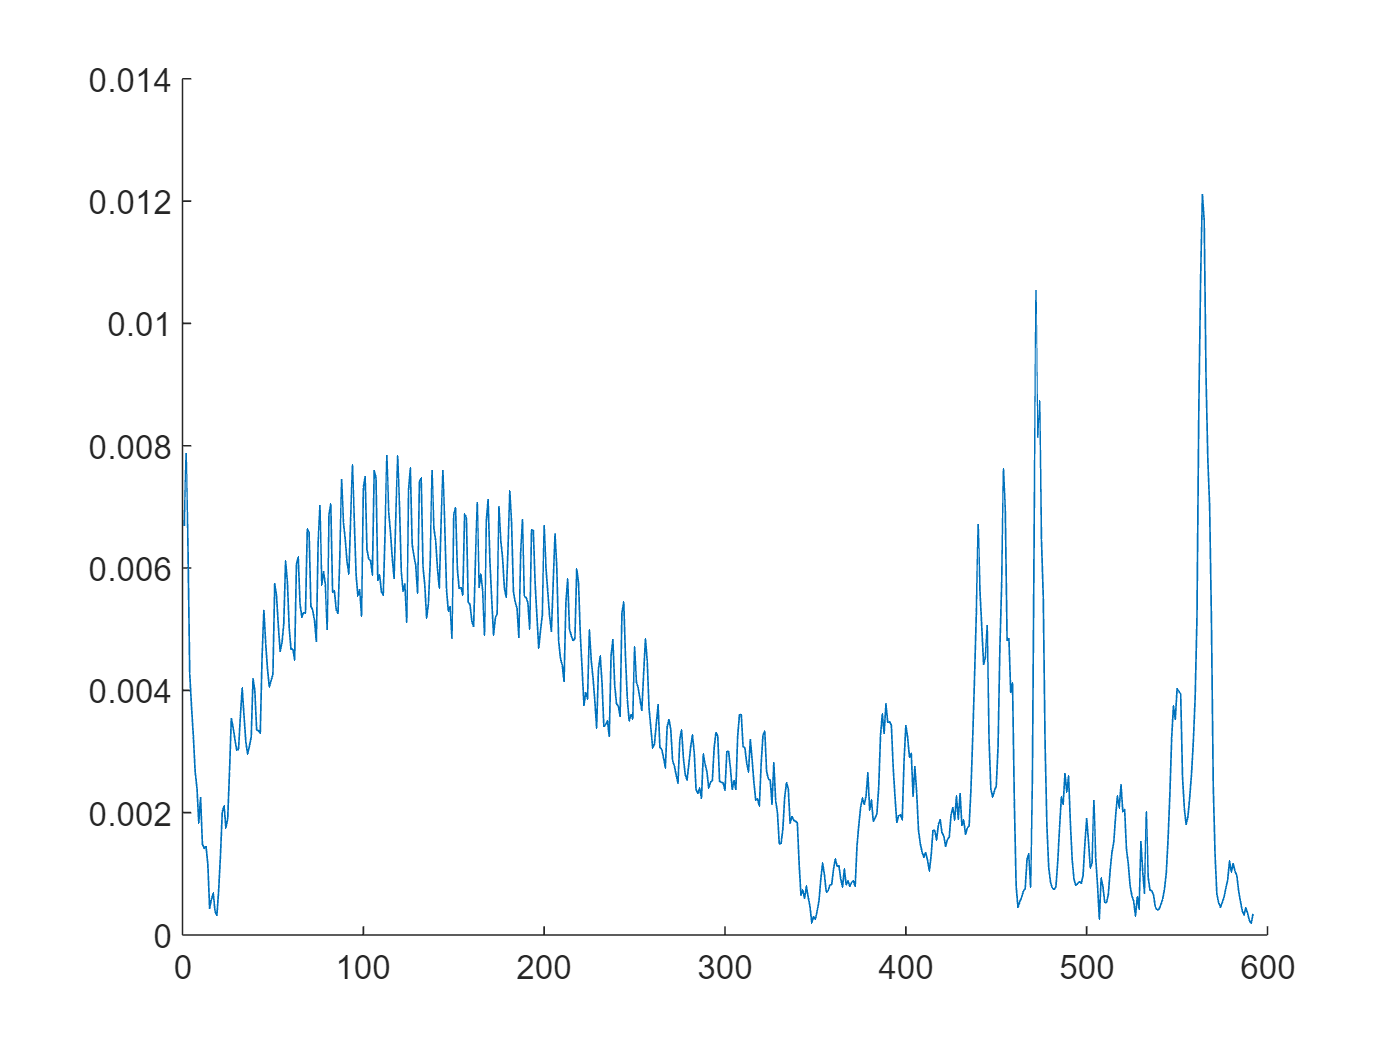


clf
hold on
plot(mean(abs(prediction(:, 10:end)-X_ref(:, 10:end)),1))

**2.4)**

Solve the data assimilation problem using a sequential importance sampling (SIS) approach, with two different proposal transition densities (your choice) selected out of the following list: 

- EnKF

prediction = donald_ENKF_63b(m, X_ens_b, X_obvs_ens, X_ref, H, time_steps, n_states, n_particles, 1);

w = 1.0e-03 *

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


X_prediction =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ans = 0

ans = 0.0070

Reampling!


ans = 0.0500

ans = 0.0183

Reampling!


ans = 0.1000

ans = 0.0143

Reampling!


ans = 0.1500

ans = 0.0026

Reampling!


ans = 0.2000

ans = 0.0023

ans = 0.2500

ans = 0.0024

Reampling!


ans = 0.3000

ans = 0.0032

ans = 0.3500

ans = 0.0034

ans = 0.4000

ans = 0.0029

ans = 0.4500

ans = 0.0042

ans = 0.5000

ans = 0.0049

ans = 0.5500

ans = 0.0043

ans = 0.6000

ans = 0.0046

ans = 0.6500

ans = 0.0044

ans = 0.7000

ans = 0.0039

ans = 0.7500

ans = 0.0054

ans = 0.8000

ans = 0.0057

ans = 0.8500

ans = 0.0047

ans = 0.9000

ans = 0.0046

ans = 0.9500

ans = 0.0043

ans = 1

ans = 0.0042

ans = 1.0500

ans = 0.0050

ans = 1.1000

ans = 0.0059

ans = 1.1500

ans = 0.0051

ans = 1.2000

ans = 0.0049

ans = 1.2500

ans = 0.0045

ans = 1.3000

ans = 0.0044

ans = 1.3500

ans = 0.0052

ans = 1.4000

ans = 0.0058

ans = 1.4500

ans = 0.0051

ans = 1.5000

ans = 0.0046

ans = 1.5500

ans = 0.0041

ans = 1.6000

ans = 0.0043

ans = 1.6500

ans = 0.0045

ans = 1.7000

ans = 0.0058

ans = 1.7500

ans = 0.0055

ans = 1.8000

ans = 0.0049

ans = 1.8500

ans = 0.0045

ans = 1.9000

ans = 0.0046

ans = 1.9500

ans = 0.0047

ans = 2

ans = 0.0058

ans = 2.0500

ans = 0.0054

ans = 2.1000

ans = 0.0046

ans = 2.1500

ans = 0.0043

ans = 2.2000

ans = 0.0043

ans = 2.2500

ans = 0.0039

ans = 2.3000

ans = 0.0055

ans = 2.3500

ans = 0.0059

ans = 2.4000

ans = 0.0047

Reampling!


ans = 2.4500

ans = 0.0049

ans = 2.5000

ans = 0.0048

ans = 2.5500

ans = 0.0042

ans = 2.6000

ans = 0.0057

ans = 2.6500

ans = 0.0059

ans = 2.7000

ans = 0.0047

ans = 2.7500

ans = 0.0046

ans = 2.8000

ans = 0.0043

ans = 2.8500

ans = 0.0043

ans = 2.9000

ans = 0.0050

ans = 2.9500

ans = 0.0059

ans = 3

ans = 0.0052

ans = 3.0500

ans = 0.0050

ans = 3.1000

ans = 0.0046

ans = 3.1500

ans = 0.0045

ans = 3.2000

ans = 0.0052

ans = 3.2500

ans = 0.0059

ans = 3.3000

ans = 0.0052

ans = 3.3500

ans = 0.0046

ans = 3.4000

ans = 0.0041

ans = 3.4500

ans = 0.0043

ans = 3.5000

ans = 0.0042

ans = 3.5500

ans = 0.0057

ans = 3.6000

ans = 0.0056

ans = 3.6500

ans = 0.0048

ans = 3.7000

ans = 0.0046

ans = 3.7500

ans = 0.0046

ans = 3.8000

ans = 0.0046

ans = 3.8500

ans = 0.0057

ans = 3.9000

ans = 0.0055

ans = 3.9500

ans = 0.0045

ans = 4

ans = 0.0044

ans = 4.0500

ans = 0.0042

ans = 4.1000

ans = 0.0039

ans = 4.1500

ans = 0.0052

ans = 4.2000

ans = 0.0057

ans = 4.2500

ans = 0.0046

ans = 4.3000

ans = 0.0047

ans = 4.3500

ans = 0.0045

ans = 4.4000

ans = 0.0040

ans = 4.4500

ans = 0.0053

ans = 4.5000

ans = 0.0055

ans = 4.5500

ans = 0.0045

ans = 4.6000

ans = 0.0043

ans = 4.6500

ans = 0.0040

ans = 4.7000

ans = 0.0040

ans = 4.7500

ans = 0.0045

ans = 4.8000

ans = 0.0055

ans = 4.8500

ans = 0.0050

ans = 4.9000

ans = 0.0047

ans = 4.9500

ans = 0.0043

ans = 5

ans = 0.0042

ans = 5.0500

ans = 0.0048

ans = 5.1000

ans = 0.0055

ans = 5.1500

ans = 0.0049

ans = 5.2000

ans = 0.0042

ans = 5.2500

ans = 0.0038

ans = 5.3000

ans = 0.0040

ans = 5.3500

ans = 0.0038

ans = 5.4000

ans = 0.0052

ans = 5.4500

ans = 0.0053

ans = 5.5000

ans = 0.0045

ans = 5.5500

ans = 0.0043

ans = 5.6000

ans = 0.0043

ans = 5.6500

ans = 0.0042

ans = 5.7000

ans = 0.0052

ans = 5.7500

ans = 0.0050

ans = 5.8000

ans = 0.0039

ans = 5.8500

ans = 0.0039

ans = 5.9000

ans = 0.0038

ans = 5.9500

ans = 0.0036

ans = 6

ans = 0.0045

ans = 6.0500

ans = 0.0051

ans = 6.1000

ans = 0.0042

ans = 6.1500

ans = 0.0043

ans = 6.2000

ans = 0.0040

ans = 6.2500

ans = 0.0037

ans = 6.3000

ans = 0.0047

ans = 6.3500

ans = 0.0050

ans = 6.4000

ans = 0.0041

ans = 6.4500

ans = 0.0038

ans = 6.5000

ans = 0.0034

ans = 6.5500

ans = 0.0035

ans = 6.6000

ans = 0.0036

ans = 6.6500

ans = 0.0047

ans = 6.7000

ans = 0.0045

ans = 6.7500

ans = 0.0040

ans = 6.8000

ans = 0.0037

ans = 6.8500

ans = 0.0037

ans = 6.9000

ans = 0.0040

ans = 6.9500

ans = 0.0047

ans = 7

ans = 0.0043

ans = 7.0500

ans = 0.0035

ans = 7.1000

ans = 0.0033

ans = 7.1500

ans = 0.0033

ans = 7.2000

ans = 0.0031

ans = 7.2500

ans = 0.0041

ans = 7.3000

ans = 0.0045

ans = 7.3500

ans = 0.0036

ans = 7.4000

ans = 0.0037

ans = 7.4500

ans = 0.0035

ans = 7.5000

ans = 0.0032

ans = 7.5500

ans = 0.0042

ans = 7.6000

ans = 0.0042

ans = 7.6500

ans = 0.0034

ans = 7.7000

ans = 0.0032

ans = 7.7500

ans = 0.0030

ans = 7.8000

ans = 0.0031

ans = 7.8500

ans = 0.0034

ans = 7.9000

ans = 0.0042

ans = 7.9500

ans = 0.0038

ans = 8

ans = 0.0036

ans = 8.0500

ans = 0.0033

ans = 8.1000

ans = 0.0032

ans = 8.1500

ans = 0.0037

ans = 8.2000

ans = 0.0041

ans = 8.2500

ans = 0.0036

ans = 8.3000

ans = 0.0030

ans = 8.3500

ans = 0.0027

ans = 8.4000

ans = 0.0028

ans = 8.4500

ans = 0.0025

ans = 8.5000

ans = 0.0036

ans = 8.5500

ans = 0.0037

ans = 8.6000

ans = 0.0031

ans = 8.6500

ans = 0.0030

ans = 8.7000

ans = 0.0029

ans = 8.7500

ans = 0.0028

Reampling!


ans = 8.8000

ans = 0.0036

ans = 8.8500

ans = 0.0035

ans = 8.9000

ans = 0.0028

ans = 8.9500

ans = 0.0027

ans = 9

ans = 0.0025

ans = 9.0500

ans = 0.0025

ans = 9.1000

ans = 0.0028

ans = 9.1500

ans = 0.0035

ans = 9.2000

ans = 0.0030

ans = 9.2500

ans = 0.0029

ans = 9.3000

ans = 0.0027

ans = 9.3500

ans = 0.0025

ans = 9.4000

ans = 0.0030

ans = 9.4500

ans = 0.0032

ans = 9.5000

ans = 0.0029

ans = 9.5500

ans = 0.0024

ans = 9.6000

ans = 0.0023

ans = 9.6500

ans = 0.0023

ans = 9.7000

ans = 0.0021

ans = 9.7500

ans = 0.0029

ans = 9.8000

ans = 0.0030

ans = 9.8500

ans = 0.0025

ans = 9.9000

ans = 0.0024

ans = 9.9500

ans = 0.0024

ans = 10

ans = 0.0023

ans = 10.0500

ans = 0.0028

ans = 10.1000

ans = 0.0028

ans = 10.1500

ans = 0.0022

ans = 10.2000

ans = 0.0021

ans = 10.2500

ans = 0.0019

ans = 10.3000

ans = 0.0020

ans = 10.3500

ans = 0.0022

ans = 10.4000

ans = 0.0027

ans = 10.4500

ans = 0.0024

ans = 10.5000

ans = 0.0023

ans = 10.5500

ans = 0.0021

ans = 10.6000

ans = 0.0020

ans = 10.6500

ans = 0.0024

ans = 10.7000

ans = 0.0026

ans = 10.7500

ans = 0.0022

ans = 10.8000

ans = 0.0018

ans = 10.8500

ans = 0.0018

ans = 10.9000

ans = 0.0018

ans = 10.9500

ans = 0.0016

ans = 11

ans = 0.0022

ans = 11.0500

ans = 0.0023

ans = 11.1000

ans = 0.0019

ans = 11.1500

ans = 0.0018

ans = 11.2000

ans = 0.0018

ans = 11.2500

ans = 0.0018

ans = 11.3000

ans = 0.0022

ans = 11.3500

ans = 0.0021

ans = 11.4000

ans = 0.0018

ans = 11.4500

ans = 0.0016

ans = 11.5000

ans = 0.0015

ans = 11.5500

ans = 0.0016

ans = 11.6000

ans = 0.0016

ans = 11.6500

ans = 0.0021

ans = 11.7000

ans = 0.0019

ans = 11.7500

ans = 0.0018

ans = 11.8000

ans = 0.0017

ans = 11.8500

ans = 0.0015

ans = 11.9000

ans = 0.0019

ans = 11.9500

ans = 0.0021

ans = 12

ans = 0.0019

ans = 12.0500

ans = 0.0015

ans = 12.1000

ans = 0.0015

ans = 12.1500

ans = 0.0015

ans = 12.2000

ans = 0.0014

ans = 12.2500

ans = 0.0019

ans = 12.3000

ans = 0.0020

ans = 12.3500

ans = 0.0017

ans = 12.4000

ans = 0.0017

ans = 12.4500

ans = 0.0017

ans = 12.5000

ans = 0.0016

ans = 12.5500

ans = 0.0020

ans = 12.6000

ans = 0.0021

ans = 12.6500

ans = 0.0018

ans = 12.7000

ans = 0.0015

ans = 12.7500

ans = 0.0015

ans = 12.8000

ans = 0.0015

ans = 12.8500

ans = 0.0014

ans = 12.9000

ans = 0.0020

ans = 12.9500

ans = 0.0018

ans = 13

ans = 0.0017

ans = 13.0500

ans = 0.0016

Reampling!


ans = 13.1000

ans = 0.0015

ans = 13.1500

ans = 0.0019

ans = 13.2000

ans = 0.0020

ans = 13.2500

ans = 0.0018

ans = 13.3000

ans = 0.0015

ans = 13.3500

ans = 0.0015

ans = 13.4000

ans = 0.0014

ans = 13.4500

ans = 0.0014

ans = 13.5000

ans = 0.0018

ans = 13.5500

ans = 0.0019

ans = 13.6000

ans = 0.0016

ans = 13.6500

ans = 0.0016

ans = 13.7000

ans = 0.0016

ans = 13.7500

ans = 0.0015

ans = 13.8000

ans = 0.0019

ans = 13.8500

ans = 0.0020

ans = 13.9000

ans = 0.0018

ans = 13.9500

ans = 0.0015

ans = 14

ans = 0.0014

ans = 14.0500

ans = 0.0014

ans = 14.1000

ans = 0.0013

ans = 14.1500

ans = 0.0019

ans = 14.2000

ans = 0.0018

ans = 14.2500

ans = 0.0016

ans = 14.3000

ans = 0.0015

ans = 14.3500

ans = 0.0014

ans = 14.4000

ans = 0.0016

ans = 14.4500

ans = 0.0019

ans = 14.5000

ans = 0.0019

ans = 14.5500

ans = 0.0016

ans = 14.6000

ans = 0.0014

ans = 14.6500

ans = 0.0013

ans = 14.7000

ans = 0.0014

ans = 14.7500

ans = 0.0014

ans = 14.8000

ans = 0.0017

ans = 14.8500

ans = 0.0014

ans = 14.9000

ans = 0.0014

ans = 14.9500

ans = 0.0013

ans = 15

ans = 0.0012

ans = 15.0500

ans = 0.0016

ans = 15.1000

ans = 0.0017

ans = 15.1500

ans = 0.0016

ans = 15.2000

ans = 0.0013

ans = 15.2500

ans = 0.0012

ans = 15.3000

ans = 0.0012

ans = 15.3500

ans = 0.0012

ans = 15.4000

ans = 0.0015

ans = 15.4500

ans = 0.0016

ans = 15.5000

ans = 0.0014

ans = 15.5500

ans = 0.0012

ans = 15.6000

ans = 0.0012

ans = 15.6500

ans = 0.0013

ans = 15.7000

ans = 0.0015

ans = 15.7500

ans = 0.0016

ans = 15.8000

ans = 0.0014

ans = 15.8500

ans = 0.0011

ans = 15.9000

ans = 0.0010

ans = 15.9500

ans = 0.0011

ans = 16

ans = 0.0010

ans = 16.0500

ans = 0.0013

ans = 16.1000

ans = 0.0012

ans = 16.1500

ans = 0.0011

Reampling!


ans = 16.2000

ans = 7.4889e-04

ans = 16.2500

ans = 7.4964e-04

ans = 16.3000

ans = 9.2680e-04

ans = 16.3500

ans = 9.5166e-04

ans = 16.4000

ans = 9.1369e-04

ans = 16.4500

ans = 8.2683e-04

ans = 16.5000

ans = 6.9279e-04

ans = 16.5500

ans = 6.6825e-04

ans = 16.6000

ans = 6.3773e-04

ans = 16.6500

ans = 7.6527e-04

ans = 16.7000

ans = 8.5656e-04

ans = 16.7500

ans = 7.4142e-04

ans = 16.8000

ans = 6.8904e-04

ans = 16.8500

ans = 6.9333e-04

ans = 16.9000

ans = 6.8482e-04

ans = 16.9500

ans = 8.5427e-04

ans = 17

ans = 8.9375e-04

ans = 17.0500

ans = 8.0931e-04

ans = 17.1000

ans = 6.9076e-04

ans = 17.1500

ans = 6.3759e-04

ans = 17.2000

ans = 5.2490e-04

ans = 17.2500

ans = 5.4674e-04

ans = 17.3000

ans = 6.0997e-04

ans = 17.3500

ans = 7.1061e-04

ans = 17.4000

ans = 5.8678e-04

ans = 17.4500

ans = 4.9888e-04

ans = 17.5000

ans = 5.1133e-04

ans = 17.5500

clf
hold on
plot(mean(abs(prediction(:, 10:end)-X_ref(:, 10:end)),1))

- Nudging

prediction = donald_nudge_63(m, X_ens_b, X_obvs_ens, X_ref, H, time_steps, n_states, n_particles, 1);
clf
hold on
plot(mean(abs(prediction(:, 10:end)-X_ref(:, 10:end)),1))


clf
hold on
plot(mean(abs(prediction(:, 10:end)-X_ref(:, 10:end)),1))